# staticな学習データをGPR

テストデータとも比較して，精度も確認する．

シンプルに解いて，オイラーの回転運動方程式を解いてlight curveを計算して，比較する．

csvの中身：

- xTrain: [q, satPos, obsPos, sunPos]

- yTrain: [mApp]

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(strcat(curdir, '/../../gpryui/'));

tStart = tic;

### input values directly

% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean"

inputGP = "attitude, position, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"

predictionStep = 1; % 1:ode, 2: simpleGP as a prediction model
validData = "boxWing_lcAtti_onOrbit.mat"


validData = "boxWing_lcAtti_onOrbit.mat"

tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
% tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

tSpanPast = 20;

### read data

% read train data ------
datadir = strcat(curdir, '/../../data/static/');
cddir = datadir;
cd(cddir)
trainStruct = dir('*.csv');
trainDF = [];
for i = 1:1:size(trainStruct, 1)
    fName = trainStruct(i).name;
    df = readmatrix(fName); % [t_jd, mApp, q, r, obsECI, sunPosI, mApp_pastMean], nIniCon x 16
    trainDF = [trainDF; df];
end
cd(curdir)

% read valid data -----
valid = load(validData); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

### data handling

% train data ------

outputDim = 1; % [mApp]
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    % inputDim = 11; % [q, r, obsECI, mApp_pastMean], nx11, sunPosI はほぼ動いてないとして入力に入れない
    x_train = trainDF(:,3:end);
    
    % 入力のorderを揃えたい
    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);
    
    % x_train_r = x_train_r ./ max(x_train_r, [], "all");
    % x_train_obsECI = x_train_obsECI ./ max(x_train_obsECI, [], "all");
    r_valid_max = max(valid.r, [], "all");
    obsECI_valid_max = max(valid.obsECI, [], "all");
    x_train_r = x_train_r ./ r_valid_max;
    x_train_obsECI = x_train_obsECI ./ obsECI_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_r, x_train_obsECI, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif
    x_train = 

elseif strcmp(inputGP, "attitude, mApp_pastMean")
    % inputDim = 5; % [q, mApp_pastMean]
    x_train = [trainDF(:,3:6), trainDF(:,end)]; % [q, mApp_pastMean]
    inputDim = size(x_train, 2);
end
y_train = trainDF(:, 2); % [mApp]

% light curve の inf を処理
y_train(isinf(y_train)) = NaN;
y_train = fillmissing(y_train, 'previous'); % mAppのinfを直前の値に置換
x_train(isinf(x_train)) = NaN;
x_train = fillmissing(x_train, 'previous'); % mApp_pastMeanの inf 処理
valid.mApp(isinf(valid.mApp)) = NaN;
valid.mApp = fillmissing(valid.mApp, 'previous'); % 真値のmAppも処理

% train data の各スカラー出力の平均を0にする for GPR
y_train_mean = mean(y_train); % [1, 1]
y_train = y_train - y_train_mean; % [:, 1], broadcasting


% valid data
t_ = valid.t_;
sat = valid.sat;
showSC(sat, "Normal", "on") % visualize satellite


### create a GP model (x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do) as a .mat file

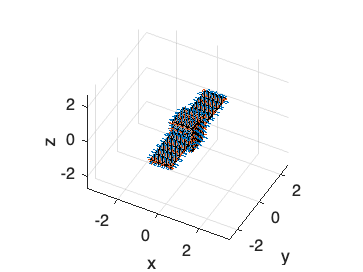

tStartLearning = tic;
% [K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]

K_Dp = 0; Kinv_Dp = 0; % 時間短縮のために一旦0で．．
[K_Do, Kinv_Do] = kernelMatrix(x_train(:,1:inputDim), params); % 
tEndLearning = toc(tStartLearning) / 60;
strcat("calculation time for learning [min] : ", num2str(tEndLearning))
fName = 'constGP';
save(strcat(fName, '.mat'), 'x_train', 'y_train', 'y_train_mean', 'K_Dp', 'Kinv_Dp', 'K_Do', 'Kinv_Do', 'params', '-v7.3');

## 逐次的に回帰を行い，回帰モデルの精度を確認

### conditions for ode

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

ans = "calculation time for learning [min] : 18.2567"


% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

tle = readTLE('JCSAT2_edited.txt', const);
jd = tle.jd;

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

rIni = valid.r(1,:);
vIni = valid.v(1,:);
qIni = valid.q(1,:);
wIni = valid.w(1,:);

xIni = [rIni, vIni, qIni, wIni];

obsECIIni = valid.obsECI(1,:);
sunPosIIni = valid.sunPosI(1,:);
mApp_pastMeanIni = valid.mApp(1,1);

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

### ode と gpr を回して逐次的に回帰

% preallocation
x_reg = zeros(size(t_, 1), inputDim); % preallocation [q, satPos, obsPos, sunPos]. inputs for regression
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    x_reg(1,:) = [qIni, rIni./r_valid_max, obsECIIni./obsECI_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    x_reg = [qIni, mApp_pastMeanIni];
end

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_,1), outputDim); % [mApp]
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu));

for i = 1:1:size(t_, 1)-1

- gpr (observation step)

    [y_reg_mu(i,1), y_reg_var(i,1)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
    y_reg(i,1) = y_reg_mu(i,1) + y_train_mean(1,1);
    % y_reg(i,1) = y_reg_mu(i,1);

- predictionStep == 1. input: x_ode, output: x (1 step 後のodeに必要なx)

    if predictionStep == 1
        [t, x] = ode45(@(t, x)eomAttiOrb_h(t,x,const,earthVSOP,sat,jd), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,1:4) = x_ode(i+1,7:10); % [q]
        % x_reg(i+1,5:13) = x_reg(i,5:13); % [satPos, obsPos, sunPos]
        if strcmp(inputGP, "attitude, position, mApp_pastMean")
        % tstep_span後の位置情報が欲しい -----------
            x_reg(i+1,5:7) = x_ode(i+1,1:3) ./ r_valid_max; % [r]
    
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            x_reg(i+1,8:10) =  obsECI_tmp(end,:) ./ obsECI_valid_max; % [obsECI]
    
            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
            % x_reg(i+1,11:13) = sunPosI_tmp(end,:); % [sunPosI] % 一旦無視
        elseif strcmp(inputGP, "attitude, mApp_pastMean")
        end
    
        x_reg(i+1, inputDim) = (x_reg(i, inputDim) * tSpanPast + valid.mApp(i+1,1)) / (tSpanPast+1); % [mApp_pastMean], 観測値を使う．

- predictionStep == 2. input: x_reg(i, :), output: y_reg_mu(i, 2:end)

    elseif predictionStep == 2
        for j = 2:1:size(y_reg_mu, 2)
            [y_reg_mu(i+1,j), y_reg_var(i+1,j)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train(:,j), params, Kinv_Dp); % input: 
        end
        y_reg_mu(i,2:end) = y_reg_mu(i,2:end) + y_train_mean(i,2:end);
        y_reg(i+1,2:5) = qMult_h(y_reg(i,2:5), rv2q(y_reg_mu(i,2:4)));
        y_reg(i+1,6:end) = y_reg(i,6:end) + y_reg_mu(i,5:end);

    end
end

- 最後にもう一回 observation step

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(x_reg(end, :), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
y_reg(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); 
% y_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

### plot

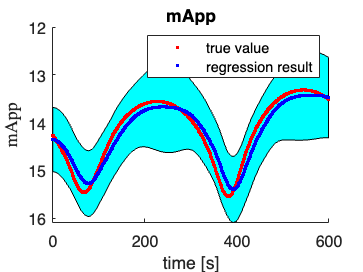

mkdir ../results/GP_static/
savedir = strcat(curdir, '/../results/GP_static/');


fignames = ["mApp"];
x_label = "time [s]";
y_labels = ["mApp"];

figure('Name', fignames(1));
plot_gpr(t_, y_reg(:,1), valid.mApp, y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);